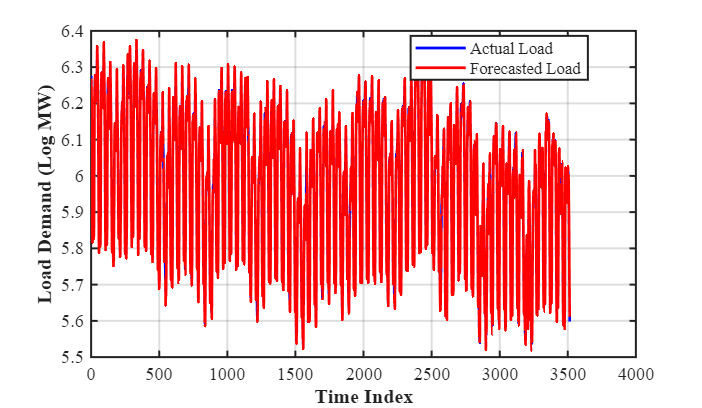

clc; clear; close all;

% ARMA Load Forecasting Model

% Load data & preprocessing

data = readtable('data/Complete_datasheet.csv');

y = double(data.Log_MW);

y = fillmissing(y,'linear');
y = filloutliers(y,'linear');

T = length(y);


train_ratio = 0.80;
Ttrain = floor(train_ratio*T);

y_train = y(1:Ttrain);

% ARMA MODEL

p = 4;
q = 2;

model = arima(p,0,q);

estModel = estimate(model,y_train,'Display','off');

y_pred = nan(T,1);

for t = Ttrain:(T-1)
    
    y_hist = y(1:t);
    
    y_next = forecast(estModel,1,'Y0',y_hist);
    
    y_pred(t+1) = y_next;
end

valid = Ttrain+1:T;

% Figures
figure('Color','w','Position',[100 100 720 420]);

plot(y(valid),'b','LineWidth',1.6); hold on;
plot(y_pred(valid),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'ARMA_Actual_vs_Forecast.png','Resolution',600);

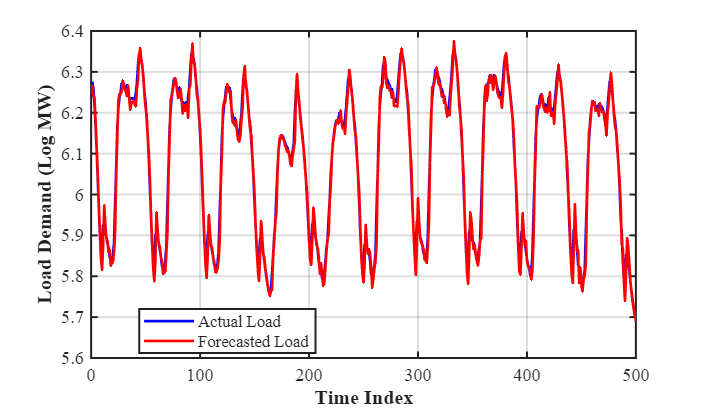


figure('Color','w','Position',[120 120 720 420]);

plot(y(valid(1:500)),'b','LineWidth',1.6); hold on;
plot(y_pred(valid(1:500)),'r','LineWidth',1.6);

grid on;
box on;

xlabel('Time Index','FontSize',12,'FontWeight','bold');
ylabel('Load Demand (Log MW)','FontSize',12,'FontWeight','bold');

legend({'Actual Load','Forecasted Load'},...
    'Location','best','FontSize',10);

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'ARMA_Zoom_View.png','Resolution',600);

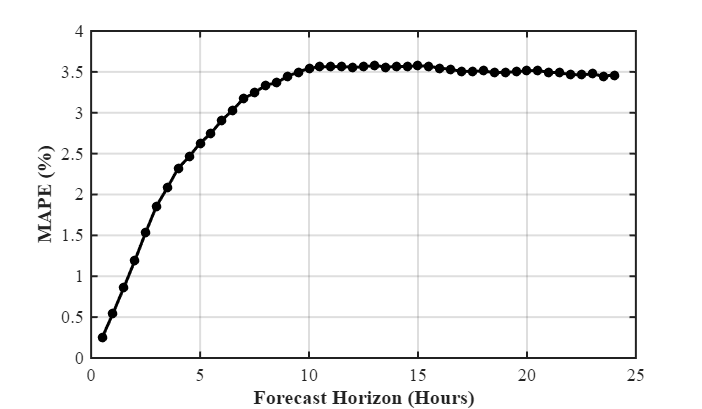


max_h = 48;
MAPE = zeros(max_h,1);

step = 10;   % speed-up

for h = 1:max_h
    
    err = [];
    
    for t = Ttrain:step:(T-h)
        
        y_hist = y(1:t);
        
        y_forecast = forecast(estModel,h,'Y0',y_hist);
        
        y_hat = y_forecast(end);
        y_true = y(t+h);
        
        if y_true ~= 0
            err = [err; abs((y_true-y_hat)/y_true)];
        end
    end
    
    MAPE(h) = mean(err)*100;
end

figure('Color','w','Position',[140 140 720 420]);

plot((1:max_h)/2,MAPE,'k-o',...
    'LineWidth',1.8,...
    'MarkerSize',4,...
    'MarkerFaceColor','k');

grid on;
box on;

xlabel('Forecast Horizon (Hours)',...
    'FontSize',12,'FontWeight','bold');

ylabel('MAPE (%)',...
    'FontSize',12,'FontWeight','bold');

set(gca,...
    'FontName','Times New Roman',...
    'FontSize',11,...
    'LineWidth',1.2);

exportgraphics(gcf,'ARMA_MAPE_vs_Horizon.png','Resolution',600);


% Table Output

horizon = (1:max_h)'/2;

MAPE_Table = table(horizon,MAPE,...
    'VariableNames',{'Horizon_Hours','MAPE_percent'});

disp(MAPE_Table);

    Horizon_Hours    MAPE_percent
    _____________    ____________

         0.5           0.24508   
           1           0.54429   
         1.5           0.86147   
           2            1.1875   
         2.5            1.5333   
           3            1.8586   
         3.5            2.0838   
           4            2.3229   
         4.5            2.4625   
           5            2.6284   
         5.5            2.7486   
           6            2.9095   
         6.5            3.0322   
           7            3.1765   
         7.5            3.2427   
           8            3.3381   
         8.5            3.3644   
           9            3.4442   
         9.5            3.4975   
          10             3.545   
        10.5            3.5625   
          11            3.5636   
        11.5            3.5656   
          12            3.5565   
        12.5            3.5606   
          13 


writetable(MAPE_Table,'ARMA_MAPE_Table.csv');

% Error Metrics

rmse = sqrt(mean((y(valid)-y_pred(valid)).^2));
mae  = mean(abs(y(valid)-y_pred(valid)));

fprintf('\nRMSE = %.4f\n',rmse);


RMSE = 0.0216


fprintf('MAE  = %.4f\n',mae);

MAE  = 0.0159



disp('Saved Files:');

Saved Files:


disp('1. ARMA_Actual_vs_Forecast.png');

1. ARMA_Actual_vs_Forecast.png


disp('2. ARMA_Zoom_View.png');

2. ARMA_Zoom_View.png


disp('3. ARMA_MAPE_vs_Horizon.png');

3. ARMA_MAPE_vs_Horizon.png


disp('4. ARMA_MAPE_Table.csv');

4. ARMA_MAPE_Table.csv
